clc
clear all
close all
load("lin_disc_7071.mat");

Ts = 0.02;

ss_d = c2d(ss_c,Ts,'zoh');
A = ss_d.A;
B = ss_d.B;
C = ss_d.C;
D = ss_d.D;

function xdot  = nlc(x, u)
    theta = x(1);
    psi = x(2);
    theta_dot = x(3);
    psi_dot = x(4);
    
    Vp = u(1);
    Vy = u(2);
    
    % Parameters
    % distance from pivot to center of rotor/propeller (m)
    Dt = 0.16743; 
    % total aero body mass (kg)
    Mb = 1.07; 
    % distance from aero body plane to center of mass below (m)
    l = 2.4e-3; 
    % Moment of inertia about pitch-axis (kg-m^2)
    Jp = 23188500.45 / 1000 * 0.001^2; % from CAD: 23188500.45 g-mm^2
    % Moment of inertia about pitch-axis (kg-m^2)
    Jy = 23810415.95 / 1000 * 0.001^2; % from CAD: 23810415.95 g-mm^2;
    % Gravity (m/s^2)
    g = 9.81;
    % Stiffness (N-m/V)
    Ksp = 0.00744;
    % Damping (N-m/V)
    Dp = 0.00199;
    % Pitch thrust gain (N/V)
    Kpp = 0.00321;
    % Pitch from yaw thrust gain (N/V)
    Kpy = 0.00137;
    % Damping (N-m/V)
    Dy = 0.00192;
    % Thrust (N-m/V)
    Kyy = 0.00610;
    % Yaw from pitch thrust gain (N/V)
    Kyp = -0.00319;
    
    theta_ddot = (Dt*Kpp*Vp + ...
                  Dt*Kpy*Vy - ...
                  Mb*g*l*cos(theta) - ...
                  Dp*theta_dot - ...
                  Ksp*theta - ...
                  Mb*psi_dot^2*l^2*sin(theta)*cos(theta)) / (Jp + Mb*l^2);
    psi_ddot = (Dt*Kyp*Vp + ...
                Dt*Kyy*Vy - ...
                Dy*psi_dot + ...
                Mb*l^2*psi_dot*theta_dot*sin(2*theta)) / (Jy + Mb*l^2*cos(theta)^2);
    
    xdot = [theta_dot, psi_dot, theta_ddot, psi_ddot]';
end

function x_next = nld(xk, uk, Ts)
    x_next = xk + Ts * nlc(xk, uk);
end

# **MPC**

[dx, du] = size(B);
dy = size(C,1);

x0 = [0 0 0 0]';
u0 = zeros(2,1);

umin = -24;
umax = 24;
delta_u_min = -1;
delta_u_max = 1;
theta_min = -0.89;
theta_max = 0.89;

Q = Ts*diag([1e4 1e3 10 50]);
R = Ts*1e-1*eye(2);
P = 1e2*Q;

Npred = 20;
Nsim = 1500;

xref = [-deg2rad(20) deg2rad(45) 0 0]';

% phi = 5*pi/6;

% % Parametrii cercului
% R_c = 3;                % Raza cercului
% omega = 2 * pi / 400;   % Viteza unghiulară (face un cerc complet la 400 de pași)
% 
% % Timpul extins pentru a acoperi și orizontul de predicție de la final
% t = 1:(Nsim + Npred); 
% 
% % Inițializăm matricea de referință
% xref = zeros(dx, length(t));
% 
% % Pozițiile (x1 și x2) pe un cerc
% xref(1, :) = -9*double(t<=100) - 9*double(t>=200 & t<=300) + 9*double(t>=400 & t<=500) + R_c * cos(omega * t + phi).*double(t>=600); 
% xref(2, :) = -9*double(t<=100) + 9*double(t>=200 & t<=300) + 9*double(t>=400 & t<=500) + R_c * sin(omega * t).*double(t>=600); 
% 
% % Vitezele (x3 și x4)
% % Viteza este derivata poziției. E bine să le dăm controllerului
% % ca referință pentru a urmări mișcarea cât mai fluid.
% xref(3, :) = -R_c * omega * sin(omega * t + phi).*double(t>=300); 
% xref(4, :) =  R_c * omega * cos(omega * t).*double(t>=300);

import casadi.*

solver = casadi.Opti();
x = solver.variable(dx, Npred+1);
u = solver.variable(du, Npred+1);
xinit = solver.parameter(dx, 1);
uinit = solver.parameter(du, 1);
xref_param = solver.parameter(dx, Npred+1);

solver.subject_to(x(:,1)==xinit)
for k = 1:Npred
    solver.subject_to(x(:, k + 1) == nld(x(:, k),u(:, k),Ts))
    solver.subject_to(umin <= u(:, k) <= umax)
    % solver.subject_to(theta_min <= x(1,k) <= theta_max)

    if k == 1
        solver.subject_to(delta_u_min <= u(:,k) - uinit <= delta_u_max)
    else
        solver.subject_to(delta_u_min <= u(:,k) - u(:,k-1) <= delta_u_max)
    end
end

objective = 0;
for k = 1:Npred
    objective = objective + (x(:,k)-xref)'*Q*(x(:,k)-xref) + u(:,k)'*R*u(:,k);
    % if k == 1
    %     objective = objective + (u(:,k)-uinit)'*R*(u(:,k)-uinit);
    % else
    %     objective = objective + (u(:,k)-u(:,k-1))'*R*(u(:,k)-u(:,k-1));
    % end
end
objective = objective + (x(:, Npred+1)-xref)'*P*(x(:, Npred+1)-xref);
solver.minimize(objective)

options.ipopt.print_level = 0;
options.ipopt.sb = 'yes';
options.print_time = 0;
solver.solver('ipopt', options)

usim = zeros(du, Nsim);
ysim = zeros(dy, Nsim);
xsim = zeros(dx, Nsim + 1);
xsim(:,1) = x0;
usim_init = u0;

timer = tic;
for i = 1:Nsim
    solver.set_value(xinit, xsim(:, i))
    solver.set_value(uinit, usim_init)
    
    % % Fără if/else! Extragem direct fereastra necesară.
    % current_xref = xref(:, i : i + Npred);
    % solver.set_value(xref_param, current_xref);

    sol = solver.solve();
    usol = sol.value(u);
    usim_init = usol(:,1);
    usim(:, i) = usol(:,1);
    xsim(:, i + 1) = nld(xsim(:, i),usim(:, i),Ts);
    ysim(:, i) = C*xsim(:,i) + D*usim(:,i);
end
time_CasAdi = toc(timer)

time_CasAdi = 76.7779

% figure
% stem(Ts*(1:Nsim),ysim(1,:));
% hold on
% grid on
% stem(Ts*(1:Nsim),ysim(2,:));
% title('output y');
% legend('$y_1$','$y_2$','interpreter','latex');
% set(gcf, 'Visible', 'on');

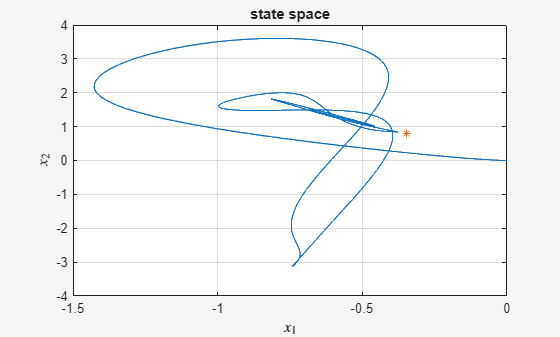

figure
plot(ysim(1,:),ysim(2,:),xref(1),xref(2),'*');

grid on
title('state space');
xlabel('$x_1$','Interpreter','latex')
ylabel('$x_2$','Interpreter','latex')
set(gcf, 'Visible','on')

% figure
% stem(usim(1,:));
% hold on
% grid on
% stem(usim(2,:));
% title('input u');
% legend('$u_1$','$u_2$','interpreter','latex');
% set(gcf, 'Visible', 'on');

% Corectura calcul eroare
error = sqrt((xsim(1, :) - xref(1)).^2 + (xsim(2, :) - xref(2)).^2 + (xsim(3, :)-xref(3)).^2 + (xsim(4, :)-xref(4)).^2);
Avg_error = mean(error)

Avg_error = 1.5583

Avg_u1 = mean(abs(usim(1,:)))

Avg_u1 = 22.5024

Avg_u2 = mean(abs(usim(2,:)))

Avg_u2 = 17.4966

% figure
% stem(Ts*(1:Nsim),xsim(3,1:Nsim));
% hold on
% grid on
% stem(Ts*(1:Nsim),xsim(4,1:Nsim));
% title('output y');
% legend('$\dot{\theta}$','$\dot{\psi}$','interpreter','latex');
% set(gcf, 'Visible', 'on');

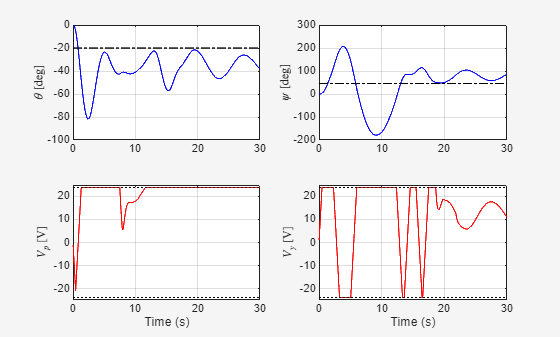

figure;
subplot(2,2,1)
plot(Ts*(1:Nsim), 180/pi*xsim(1,1:Nsim),'b-');
hold on 
grid on
plot(Ts*(1:Nsim), -20*ones(1,Nsim), 'k-.');
xlim([0 30]);
ylabel(['$\theta$' ' [deg]'], 'Interpreter','latex');
subplot(2,2,3)
plot(Ts*(1:Nsim), usim(1,:),'r-');
grid on
hold on
plot(Ts*(1:Nsim), umin*ones(1,Nsim), 'k:',Ts*(1:Nsim), umax*ones(1,Nsim), 'k:');
xlim([0 30]);
ylim([-25 25]);
ylabel(['$V_p$' ' [V]'], 'Interpreter','latex');
xlabel('Time (s)')

subplot(2,2,2)
plot(Ts*(1:Nsim), 180/pi*xsim(2,1:Nsim),'b-');
hold on 
grid on
plot(Ts*(1:Nsim), 45*ones(1,Nsim), 'k-.');
xlim([0 30]);
ylabel(['$\psi$' ' [deg]'],'Interpreter','latex');
subplot(2,2,4)
plot(Ts*(1:Nsim), usim(2,:),'r-');
grid on
hold on
plot(Ts*(1:Nsim), umin*ones(1,Nsim), 'k:',Ts*(1:Nsim), umax*ones(1,Nsim), 'k:');
xlim([0 30]);
ylim([-25 25]);
ylabel(['$V_y$' ' [V]'], 'Interpreter','latex');
xlabel('Time (s)')
set(gcf, 'visible', 'on')

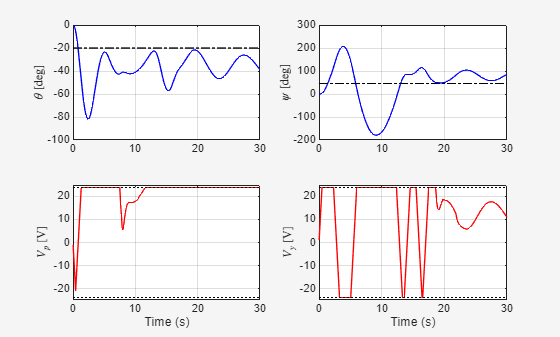

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 
 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


cleanfigure;
matlab2tikz('NMPC_sim.tex','width','\textwidth');